t = [11.6, 8.3, 6.3, 4.5, 4.0, 3.4];
F = [0.3, 0.4, 0.5, 0.7, 0.8, 0.9];

l = 0.1;
Area = l^2;

tau = F/Area;
du = l./t;
dy = 1.6*10^(-3);
dudy = du/dy;
mu = tau ./ dudy;


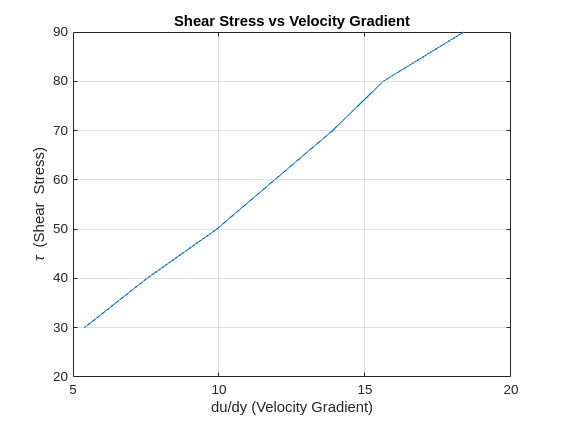

plot(dudy, tau);
title('Shear Stress vs Velocity Gradient');
xlabel('du/dy (Velocity Gradient)'); 
ylabel('\tau (Shear Stress)'); 
grid on; 

% Given data
T = 0.021; % Torque in N·m
D = 0.075; % Diameter in m
H = 0.150; % Height in m
dy = 2e-5; % Gap in m
rpm = 100; % Rotational speed in rpm

% Calculations
R = D / 2; % Radius
omega = rpm * 2 * pi / 60; % Angular velocity in rad/s
A = 2 * pi * R * H; % Surface area
tau = T / (A * R); % Shear stress
u = omega * R; % Surface velocity
dudy = u / dy; % Velocity gradient
mu = tau / dudy; % Viscosity

% Display results
fprintf('Viscosity of the liquid: %.2e Pa·s\n', mu);

Viscosity of the liquid: 8.07e-04 Pa·s
